# Natural Resources Management

# Final Project

addpath("utils\")

Dataset: **8. Gabcikovo**

## Part 0. Data pre-processing

file = readmatrix("08Gabcikovo.csv");

Error using readmatrix (line 148)
Unable to find or open '08Gabcikovo.csv'. Check the path and filename or file permissions.

data_precipitation = file(:,4); % [mm/d]
data_streamflow = file(:,5); % [m3/s]
data_temperature = file(:,6); % °C

### Dataset times

Total dataset total years and years used for training, taking 70% of the dataset

T = 365;
tr_length = 0.70;
years_total = length(file) / T
years_tr = floor(years_total*tr_length)

### Dataset partition 

% Training dataset
x_tr = data_streamflow(1:T*years_tr);
u_tr = [data_precipitation(1:T*years_tr) data_temperature(1:T*years_tr)];
% Validation dataset
x_val = data_streamflow(T*years_tr+1:end);
u_val = [data_precipitation(T*years_tr+1:end) data_temperature(T*years_tr+1:end)];

### Cyclostationary  analysis

f = 5; 
N_tr = length(x_tr);
tt = repmat([1:T]', N_tr/T, 1);
% Moving Average
[mi, m] = moving_average(x_tr, T, f);
% Moving variance
[ma_var2, s2] = moving_average((x_tr - m).^2, T, f);
ma_var = ma_var2.^(1/2);
s = s2.^(1/2);
figure;
plot(tt, [x_tr, m], '.');
xlabel('t [days] (1 year)');
hold on;
% plot([1 : T], mi, 'g', 'LineWidth',.5);
plot(tt, m + s, '.r');
plot(tt, m - s, '.r');
legend('n_t', '\mu_t', '+\sigma', '-\sigma');
% legend('n_t', '\mu_t', '\mu_{cyclo}', '+\sigma', '-\sigma');

### Correlations

#### Streamflow - Precipitations

figure; correlogram(x_tr, u_tr(:,1), years_tr)

#### Streamflow - Temperature

figure; correlogram(x_tr, u_tr(:,2), years_tr)

### Data normalization

f = 5; 
[x_norm, mean_x, sigma_x] = deseasonalize(x_tr, T, f);
[u_norm(:,1), mean_u(:,1), sigma_u(:,1)] = deseasonalize(u_tr(:,1), T, f);
[u_norm(:,2), mean_u(:,2), sigma_u(:,2)] = deseasonalize(u_tr(:,2), T, f);

[x_norm_val, mean_x_val, sigma_x_val] = deseasonalize(x_val, T, f);
[u_norm_val(:,1), mean_u_val(:,1), sigma_u_val(:,1)] = deseasonalize(u_val(:,1), T, f);
[u_norm_val(:,2), mean_u_val(:,2), sigma_u_val(:,2)] = deseasonalize(u_val(:,2), T, f);

### Correlations

#### Streamflow - Precipitations

figure; correlogram(x_norm, u_norm(:,1), years_tr)

#### Streamflow - Temperature

figure; correlogram(x_norm, u_norm(:,2), years_tr)

## Part 1. 1-day ahead forecast model

### Linear models

#### AR (n)

To find the best AR(n) model possible, the R2 index is evaluated for each model.

ar_iteation = 15;
r2_ar = nan(ar_iteation,1);
r2_ar_val = nan(ar_iteation,1);
r2_ar_val_max = 0;
ar_opt_idx = 0;
for i=1:ar_iteation
    [theta_ar_i, x_norm_ar] = trainAR(x_norm, i);
    x_norm_ar_val = estimateAR(x_norm_val, theta_ar_i, i);
    
%     Training
    r2_ar(i) = getR2Performance( ...
            x_tr, ...
            x_norm_ar, ...
            mean_x, ...
            sigma_x ...
        );
%     Validation
    r2_ar_val(i) = getR2Performance( ...
            x_val, ...
            x_norm_ar_val, ...
            mean_x_val, ...
            sigma_x_val ...
        );
    
    if r2_ar_val_max < r2_ar_val(i)
        theta_ar = theta_ar_i;
        ar_opt_idx = i;
        r2_ar_val_max = r2_ar_val(i);
    end
    
end
clear i
figure;
plot([r2_ar, r2_ar_val])
hold on 
plot (ar_opt_idx, r2_ar_val_max, '*g')
legend('Training','Validation','Max R^2_{val}')
xlabel('AR(n) order');ylabel('R^2');
grid on

#### Proper ARX (1,1)

y = x_norm(2:end);
M = [x_norm(1:end-1), u_norm(1:end-1,:)];
theta = M\y;
x_est = [x_norm(1); M*theta];
r2_arx = getR2Performance(x_tr, x_est, mean_x, sigma_x)
M_val = [x_norm_val(1:end-1), u_norm_val(1:end-1,:)];
x_est = [x_norm_val(1); M_val*theta];
r2_arx_val = getR2Performance(x_val, x_est, mean_x_val, sigma_x_val)
figure;
plot([r2_arx, r2_arx_val])

xlabel('AR(n) order');ylabel('R^2');
grid on

#### Improper ARX (1,1)

y = x_norm(2:end);
M = [x_norm(1:end-1), u_norm(2:end,:)];
theta = M\y;
x_est = [x_norm(1); M*theta];
r2_arx_imp = getR2Performance(x_tr, x_est, mean_x, sigma_x)
M_val = [x_norm_val(1:end-1), u_norm_val(1:end-1,:)];
x_est = [x_norm_val(1); M_val*theta];
r2_arx_imp_val = getR2Performance(x_val, x_est, mean_x_val, sigma_x_val)
figure;
plot([r2_arx_imp, r2_arx_imp_val])

xlabel('AR(n) order');ylabel('R^2');
grid on

### Nonlinear models

#### Proper ANN

The model used is an ANN with 3 neurons, iterated 10 times to find the best model possible.

% Train dataset
x_ann = [x_norm(1:end-1), u_norm(1:end-1,:)]';
y_ann = x_norm(2:end)';
% Validation dataset
x_ann_val = [x_norm_val(1:end-1) u_norm_val(1:end-1,:)]';

N_runs = 10;
r2_ann_prop = zeros(N_runs, 1);
r2_ann_prop_val = zeros(N_runs, 1);
ann_opt_idx = 0;
for i = 1:N_runs
    % ANN Train
    ann_prop_i = feedforwardnet(3);
    ann_prop_i = train(ann_prop_i,x_ann,y_ann);
    
    % view(ann_prop)
    y = ann_prop_i(x_ann);
    y_ann_prop = [x_norm(1); y'];
    r2_ann_prop(i) = getR2Performance(x_tr, y_ann_prop, mean_x, sigma_x);
    
    % Validation
    y = ann_prop_i(x_ann_val);
    y_ann_prop_val = [x_norm_val(1); y'];
    r2_ann_prop_val(i) = getR2Performance(x_val, y_ann_prop_val, mean_x_val, sigma_x_val);
    
    
    if r2_ann_prop_val(i) >= max(r2_ann_prop_val)
        ann_prop = ann_prop_i; % Optimal ANN wrt validation dataset
        ann_opt_idx = i;
    end
    
end


figure; 
h = bar([r2_ann_prop, r2_ann_prop_val], 'BaseValue',0.95);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Iteration');ylabel('R^2');
legend('location','southwest')

#### Improper ANN

% Train dataset
x_ann = [x_norm(1:end-1), u_norm(2:end,:)]';
y_ann = x_norm(2:end)';
% Validation dataset
x_ann_val = [x_norm_val(1:end-1) u_norm_val(1:end-1,:)]';

N_runs = 10;
r2_ann_improp = zeros(N_runs, 1);
r2_ann_improp_val = zeros(N_runs, 1);
ann_improp_opt_idx = 0;
for i = 1:N_runs
    % ANN Train
    ann_improp_i = feedforwardnet(3);
    ann_improp_i = train(ann_improp_i,x_ann,y_ann);
    
    % view(ann_prop)
    y = ann_improp_i(x_ann);
    y_ann_improp = [x_norm(1); y'];
    r2_ann_improp(i) = getR2Performance(x_tr, y_ann_improp, mean_x, sigma_x);
    
    % Validation
    y = ann_improp_i(x_ann_val);
    y_ann_improp_val = [x_norm_val(1); y'];
    r2_ann_improp_val(i) = getR2Performance(x_val, y_ann_improp_val, mean_x_val, sigma_x_val);
    
    
    if r2_ann_improp_val(i) >= max(r2_ann_improp_val)
        ann_improp = ann_improp_i; % Optimal ANN wrt validation dataset
        ann_improp_opt_idx = i;
    end
    
end


figure; 
h = bar([r2_ann_improp, r2_ann_improp_val],'BaseValue',0.944);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Iteration');ylabel('R^2');
legend('location','southwest')

#### CART

The leaf size is iterated between 1 and 40 to find the optimal leaf size

x_cart = [x_norm(1:end-1), u_norm(1:end-1,:)];
y_cart = x_norm(2:end);

x_cart_val = [x_norm_val(1:end-1), u_norm_val(1:end-1,:)];
y_cart_val = x_norm_val(2:end);
    
max_leaf_size = 40;
r2_cart = zeros(max_leaf_size,1);
r2_cart_val = zeros(max_leaf_size,1);
leafsize_opt = 0;

for i = 1:max_leaf_size
    T_i = fitrtree(x_cart, y_cart,'MinLeafSize',i);
    % view(T, 'mode', 'graph');
    y = predict(T_i, x_cart);
    y_cart_predict = [x_norm(1); y];
    r2_cart(i) = getR2Performance(x_tr, y_cart_predict, mean_x, sigma_x);
    
%     Validation
    y = predict(T_i, x_cart_val);
    y_cart_predict_val = [x_norm_val(1); y];
    r2_cart_val(i) = getR2Performance(x_val, y_cart_predict_val, mean_x_val, sigma_x_val);
    
    if r2_cart_val(i) >= max(r2_cart_val)
        T_opt = T_i; % Optimal ANN wrt validation dataset
        leafsize_opt = i;
    end 
end

figure;
plot([r2_cart, r2_cart_val])
hold on
plot (leafsize_opt, r2_cart_val(leafsize_opt), '*g')
legend('Training','Validation','Max R^2_{val}')
xlabel('Leaf size');ylabel('R^2');
grid on
view(T_opt,'mode','graph')
T_opt.NumNodes
figure
subplot(2,2,1); plot( T_opt.NodeSize ); title('Node size'); % number of samples per node
subplot(2,2,2); plot( T_opt.NodeMean ); title('Node mean'); % mean samples in each node
subplot(2,2,3); plot( T_opt.NodeError ); title('Node error'); % node error
subplot(2,2,4); plot( T_opt.NodeProbability); title('Node probability')

Then is compared with the algorithm that finds the optimal solution by a smart search of params

T_opt_auto = fitrtree(x_cart, y_cart,'OptimizeHyperparameters','auto');

y = predict(T_opt_auto, x_cart_val);
y_cart_predict_val = [x_norm_val(1); y];
r2_cart_auto_val = getR2Performance(x_val, y_cart_predict_val, mean_x_val, sigma_x_val)
c = categorical({'Iteration','Auto-tool'});
bar(c, [max(r2_cart_val); r2_cart_auto_val],'BaseValue',0.95)
xlabel('Optimal CART');ylabel('R^2');

### Models comparison

figure;
c = categorical({ ...
    'AR(1)', ...
    'AR(opt)', ...
    'ARX(1,1) Proper', ...
    'ARX(1,1) Improper', ...
    'ANN(3) Proper', ...
    'ANN(3) Improper', ...
    'CART', ...
    });

The result is that the model with the best performance (r2=0.968) is the AR(9), but a simper model as the ARX(1,1) (r2=0.962) gives almost the same, then the most suitable to implement is this one. It can be improved looking for more complex models. At the same time, the proper ANN(3) has a good performance, it can be improved adding more neurons, but taking the risk of overfitting.

r2_index = [ ...
    r2_ar(1), r2_ar_val(1); ...
    r2_ar(ar_opt_idx), r2_ar_val(ar_opt_idx); ...
    r2_arx, r2_arx_val; ...
    r2_arx_imp, r2_arx_imp_val; ...
    r2_ann_prop(ann_opt_idx), r2_ann_prop_val(ann_opt_idx); ...
    r2_ann_improp(ann_improp_opt_idx), r2_ann_improp_val(ann_improp_opt_idx); ...
    r2_cart(leafsize_opt), r2_cart_val(leafsize_opt); ...
    ]
% latex(sym(r2_index))
h = bar(c,r2_index,'BaseValue',0.9);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Estimator');ylabel('R^2');
legend("Location","southwest")
grid on

## Part 2. Damming policies

### Dam sizing

load -ascii inflowsgabcikovo.txt
data_streamflow= inflowsgabcikovo;
lake_surface = 133257.80e6; % [m2]
Q_month = dailyToMonthly(data_streamflow, years_total);
% https://www.hausamstrom.de/wp-content/uploads/2018/12/Folder_EnergieerlebnisJochenstein-eng.pdf

TODO: Target release

w = 2350*0.50; % [m3/s] Target release - Downstrem demand [% wrt...]
w = prctile(Q_month,40);
w = mean(w);
deltaT = 3600*24*[31 28 31 30 31 30 31 31 30 31 30 31]';
Q = Q_month(:).*repmat(deltaT,years_total,1) ; % [m3/month]
W = w*ones(size(Q)).*repmat(deltaT,years_total,1) ; % [m3/month]

figure;
plot(Q, '.-b'); hold on
plot(W, 'r');
legend('Inflows', 'Target release')

#### Rippl criteria

[rippl] = abs(getRipple(W,Q));
rippl/lake_surface

#### Sequent Peak Analysis criteria

[spa, K] = getSPA(W,Q);
spa/lake_surface
figure;
plot(K)

### Define Standard Operating policy

TODO: How to define the max release possible wrt the height?

One alternative is to use the value up to the mean + one standard deviation.

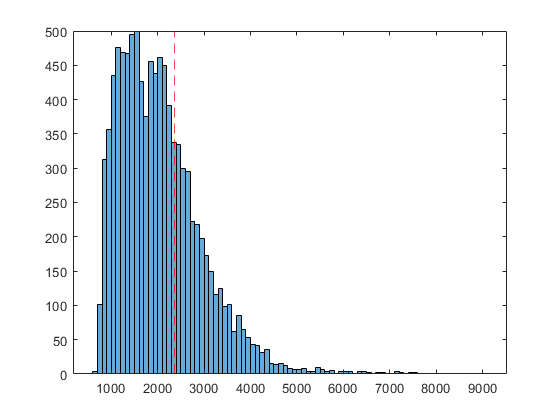

% max_nat_release_est = 3000;
max_nat_release_est = 2359; % [m3/s]
figure;
histogram(data_streamflow)
hold on;
xline(max_nat_release_est,'--r');

TODO: Where can be found the suitable parameters for the lake, to determine the natural release

file = readmatrix("data\08Gabcikovo.csv");
data_streamflow = file(:,5); % [m3/s]
% 86.6021881286577        % beta (storage-discharge relationship)
% 1.95062290363465        % alfa (storage-discharge relationship)
% -1.27                   % h0   (storage-discharge relationship)
param.nat.S = 133257.80e6;
param.nat.beta = 86.6021881286577;
param.nat.alpha = 1.95062290363465;
param.nat.h0 = -1.27;

% regulated level-discharge relationship:
param.reg.w = w;
param.reg.h_min = 0;
param.reg.h_max = 1.5;
param.reg.h1 = 0.3;
param.reg.h2 = 1;
param.reg.m1 = 300;
param.reg.m2 = 1000;

data_streamflow = [ nan; data_streamflow ]; % for time convention
h_init = 0.88; % initial condition

[s_nat, h_nat, r_nat] = simulate_nat_lake( data_streamflow, h_init, param );

Unrecognized function or variable 'simulate_nat_lake'.

[s_reg, h_reg, r_reg] = simulate_reg_lake( data_streamflow, h_init, param );

figure
subplot(211)
plot([h_nat h_reg]); ylabel('level (m)'); legend('nat', 'reg')
subplot(212)
plot([r_nat r_reg]); ylabel('release (m3/2)'); legend('nat', 'reg')


w = param.reg.w;
h_flo = 1.73;
h_nat = h_nat(2:end);
r_nat = r_nat(2:end);
% daily average squared deficit
dn = max( w-r_nat, 0 );
Iirr_nat = mean( dn.^2 )
% daily average flooded area
S_flo = zeros( size(h_nat) );
idx = find( h_nat > h_flo );
S_flo(idx) = 0.081*h_nat(idx).^3 -0.483*h_nat(idx).^2 + ...
    1.506*h_nat(idx) -1.578;
Iflo_nat = mean(S_flo)

h_reg = h_reg(2:end);
r_reg = r_reg(2:end);
% daily average squared deficit
dr = max( w-r_reg, 0 );
Iirr_reg = mean( dr.^2 )
% daily average flooded area
S_flo = zeros( size(h_reg) );
idx = find( h_reg > h_flo );
S_flo(idx) = 0.081*h_reg(idx).^3 -0.483*h_reg(idx).^2 + ...
    1.506*h_reg(idx) -1.578;
Iflo_reg = mean(S_flo)

figure
plot( Iflo_nat, Iirr_nat, 'bo')
hold on
plot( Iflo_reg, Iirr_reg, 'ro')
xlabel('flood'); ylabel('irrigation')
legend('nat', 'reg')

% ------------------------------------------
%%  IMPROVE FLOODING BY REDUCING h2 TO 0.6
% ------------------------------------------
param.reg.h2 = 0.6;

[s_reg, h_reg, r_reg] = simulate_reg_lake( data_streamflow, h_init, param );

h_reg = h_reg(2:end);
r_reg = r_reg(2:end);
% daily average squared deficit
dr = max( w-r_reg, 0 );
Iirr_reg2 = mean( dr.^2 )
% daily average flooded area
S_flo = zeros( size(h_reg) );
idx = find( h_reg > h_flo );
S_flo(idx) = 0.081*h_reg(idx).^3 -0.483*h_reg(idx).^2 + ...
    1.506*h_reg(idx) -1.578;
Iflo_reg2 = mean(S_flo)

figure
plot( Iflo_nat, Iirr_nat, 'bo')
hold on
plot( Iflo_reg, Iirr_reg, 'ro')
plot( Iflo_reg2, Iirr_reg2, 'mo')
xlabel('flood'); ylabel('irrigation')
legend('nat', 'reg', 'reg2')

figure;
plot(h_test, r_test, ':b','LineWidth',1)
hold on;
xline(param.reg.hmin,'--r');
xline(param.reg.hmax,'--r');

xline(param.reg.h1,'--g');
xline(param.reg.h2,'--g');

plot(h_test, r_reg,'k','LineWidth',1.5)
legend('Natural Release', 'h_{min}', 'h_{max}', 'h_1', 'h_2','Regulated outflow','Location','northwest')

### Trajectories Alternative-0 vs SOP

h_init = 0.4;
h_bar = 1.5; % Flooding thereshold

[r_reg, s_reg, h_reg] = simRegLakeSimplified(h_init, data_streamflow, param);
[r_nat, s_nat, h_nat] = simNatLakeSimplified(h_init, data_streamflow, param);

figure; 
plot (r_nat, ':r');
hold on; 
plot(r_reg,'b'); 
title('Release');legend('Natural','Regulated');
figure;
plot (s_nat, ':r');
hold on; 
plot(s_reg, 'b');
title('Surface');legend('Natural','Regulated');
figure; 
plot (h_nat, ':r');
hold on;
plot(h_reg, 'b');
title('Level');legend('Natural','Regulated');

### Indicators

#### Reliability

I_rel_sop = getReliability(r_reg, w)
I_rel_nat = getReliability(r_nat, w)

#### Flooding 1

I_f1_reg = getFlooding1(h_reg,h_bar,years_total)
I_fl_nat = getFlooding1(h_nat,h_bar,years_total)

#### Resilience

% I_res_reg = getResilience(r_reg,w)